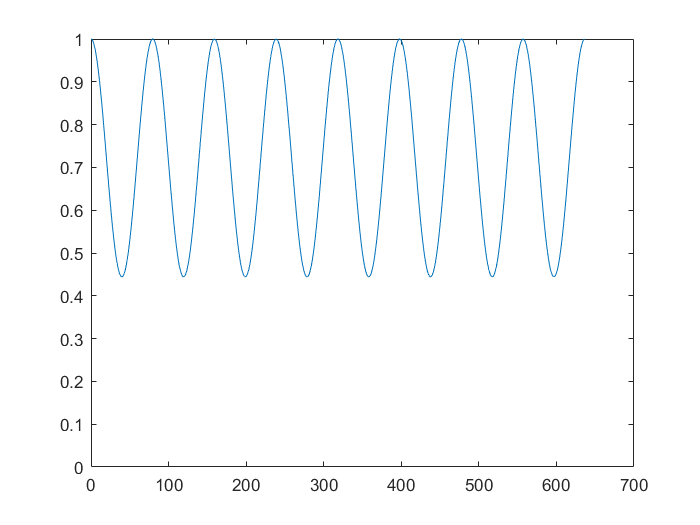


clear all;
close all;

F = 5/2;
sigmax = spinOp(F,'x');
sigmay = spinOp(F,'y');
sigmaz = spinOp(F,'z');
initial = zeros(2*F+1,1);
initial(1) = 1;
%initial=spin_coherent(pi/2,pi/2);

O1 = 2*asin(sqrt(5/6));
temp1 = zeros(2*F+1,1);
temp1(1) = 1;
temp2 = zeros(1,2*F+1);
temp2(3) = 1;
Raman1 = O1*(temp1*temp2 + temp2'*temp1')/2;

O2 = pi;
temp1 = zeros(2*F+1,1);
temp1(3) = 1;
temp2 = zeros(1,2*F+1);
temp2(5) = 1;
Raman2 = O2*(temp1*temp2 + temp2'*temp1')/2;

fB = 0.01;
TB = 1/fB;
Bz = 2*pi*fB*sigmaz;
Raman_B1 = Raman1+1*Bz;
Raman_B2 = Raman2+1*Bz;

phi1 = 2*acos(1/sqrt(6));
tau1 = 1;
state1 = ham_evolve(Raman_B1,initial,tau1);

phi2 = pi;
tau2 = 1;
state2 = ham_evolve(Raman_B2,state1,tau2);

% phi3 = pi;
% tau3 = phi3/(2*pi*fRaman);
% state3 = ham_evolve(Raman_B,state2,tau3);
% 
% phi4 = pi;
% tau4 = phi4/(2*pi*fRaman);
% state4 = ham_evolve(Raman_B,state3,tau4);

comps = state2;
%comps = conj(state2).*state2;

timelist = [0:0.001:2]*TB;

finalstate = zeros(length(timelist),2*F+1);
state4 = zeros(length(timelist),2*F+1);

for k = 1:length(timelist)
    time = timelist(k);
    finalstate(k,:) = ham_evolve(Bz, ...
        comps,time);
    temp = finalstate(k,:)';
    temp = ham_evolve(Raman_B2,temp,1);
    state4(k,:) = ham_evolve(Raman_B1,temp,1);
end

readout = (conj(state4).*state4)';

phase = readout(1,:);
figure;
plot(timelist/pi,phase);
ylim([0 1]);
set(gcf,'Visible','on');

function final = ham_evolve(ham,initial,time)
try
    final = expm(-1i*ham*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end

function state = spin_coherent(theta,phi)
sigmay = spinOp(5/2,'y');
sigmaz = spinOp(5/2,'z');
polar = [1 0 0 0 0 0]';
state1 = ham_evolve(sigmay,polar,theta);
state = ham_evolve(sigmaz,state1,phi);
end